clearvars;
close all;
clc;

## READ FILE

fileName = uigetfile('*.csv', 'Pilih file CSV yang berisi data training');
file = csvread(fileName);
[X, Y] = size(file);
class = categorical(file(:,1));
data = file(: , 2:Y);
numFeatures = size(data, 2);
numClasses = 2;

## SETUP NEURAL NETWORK LAYERS

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |       37.50% |       0.9916 |          0.0010 |
|      13 |          50 |       00:00:07 |      100.00% |       0.0320 |          0.0010 |
|      25 |         100 |       00:00:09 |      100.00% |       0.0069 |          0.0010 |
|      38 |         150 |       00:00:10 |      100.00% |       0.0508 |          0.0010 |
|      50 |         200 |       00:00:12 |      100.00% |       0.0044 |          0.0010 |
|      63 |         250 |       00:00:13 |       93.75% |       0.1227 |          0.0010 |
|      75 |         300 |       00:00:14 |      100.00% |       0.

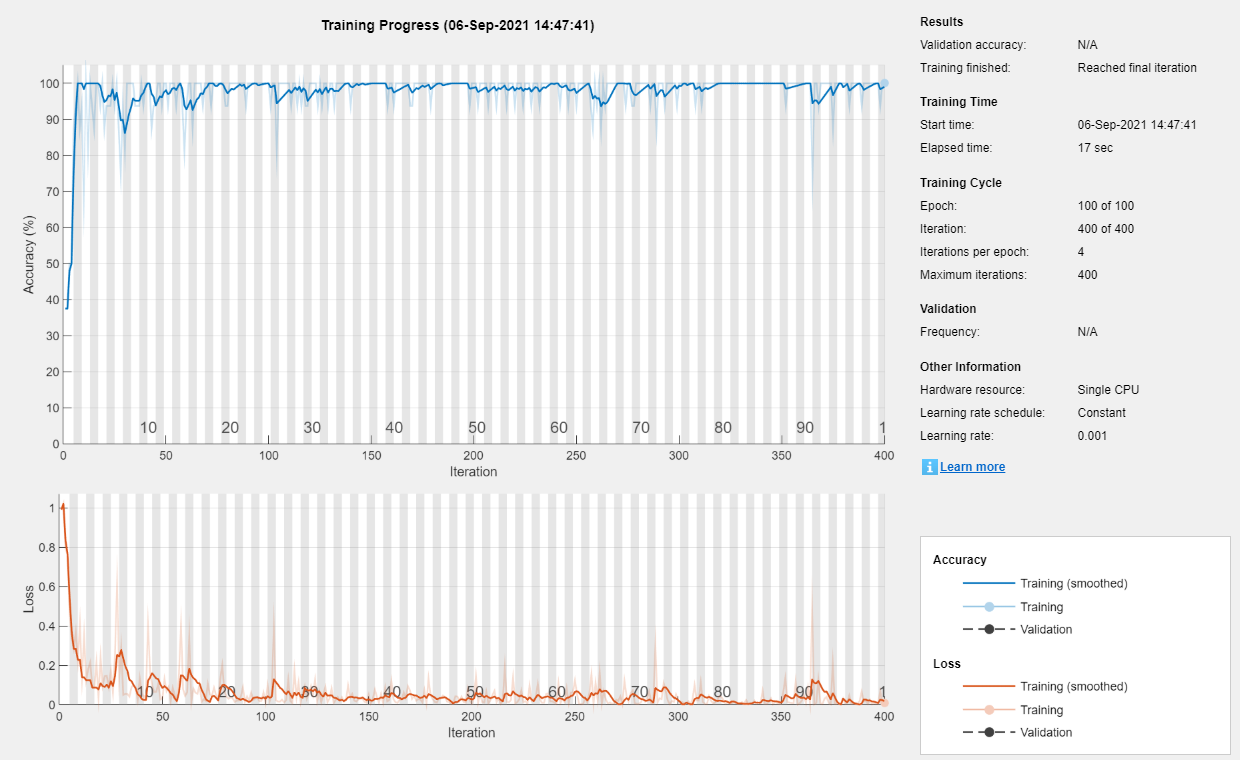

layers = [
    %input layer (480 Total Features)
    featureInputLayer(numFeatures)
    %hidden layer 1 (100 Neurons)
    fullyConnectedLayer(240)
    batchNormalizationLayer
    reluLayer
    %hidden layer 2 (50 Neurons)
%     fullyConnectedLayer(50)
%     batchNormalizationLayer
%     reluLayer
    %hidden layer 3 (50 Neurons)
%     fullyConnectedLayer(50)
%     batchNormalizationLayer
%     reluLayer
    %output neurons (Sesuai Jumlah Class : 2 Neurons)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

miniBatchSize = 16;

options = trainingOptions(...
    'adam', ... %Optimizer Function
    'MaxEpochs',100, ... %Training Cycle
    'MiniBatchSize',miniBatchSize, ... %Processed data per run
    'Shuffle','every-epoch', ... %Randomize data order every epoch
    'Plots','training-progress', ... %Display training progress window
    'Verbose',1 ... %Display Result on command window
    );

net = trainNetwork(data,class,layers,options);

network = net;
save('network_sq2.mat', 'network');